clc; clear; close all 
s = tf('s');

% parametros PID
    T = 4.42;
    L = 0.442;
    
    kp = 0.837;
    
    % ganho integral
    ti = 0.884;
    ki = kp/ti;
    
    % ganho derivativo
    td = 0.221;
    kd = kp*td;

% parametros da planta
b = 3.235;
a = 0.226;

% funçao da planta
G_p = b/((s+a))


G_p =
 
    3.235
  ---------
  s + 0.226
 
Continuous-time transfer function.
Model Properties


% funçao do controlador
C_p = (s^2*kd + s*kp + ki)/s;

L_s = G_p*C_p


L_s =
 
  0.5984 s^2 + 2.708 s + 3.063
  ----------------------------
         s^2 + 0.226 s
 
Continuous-time transfer function.
Model Properties


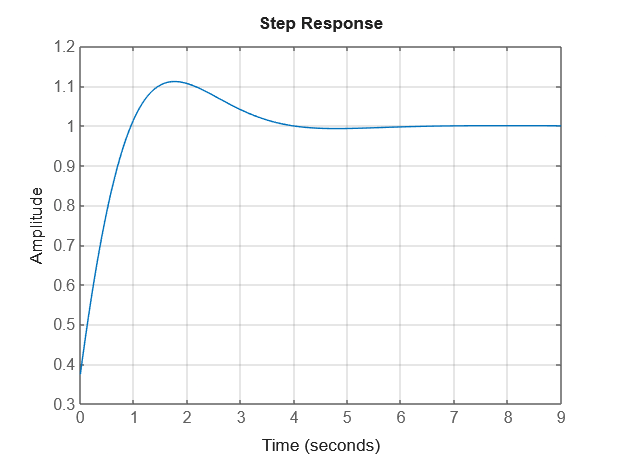

T_s = L_s/(1+L_s);
step(T_s)
grid on

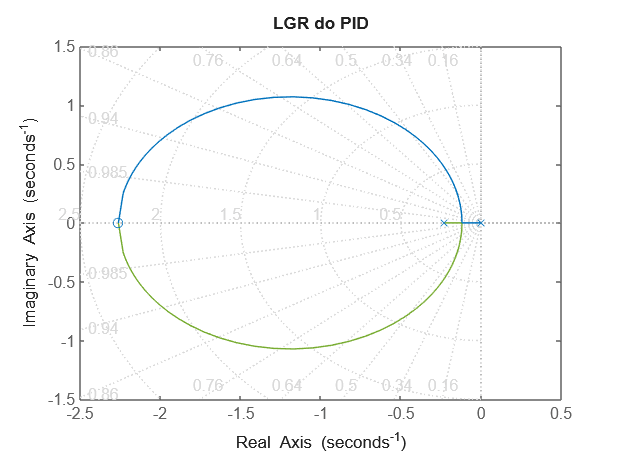

rlocus(L_s)
title('LGR do PID')
grid on